N = 2048; % Size of the IFFT block available at Tx
M = 64; % Order of QAM modulation being used at the Tx...
k = log2(M); % The number of bits each symbol will represent...
codeRate = 0.5; % The code-rate being used by the convolutional encoder at the Tx...
lenData = (N-2)*(1/2)*(k)*(codeRate); % The amount (or length) of the data we should generate...
data = randi([0 1], lenData, 1); % Our data bit stream

## Convolutional Encodingdata = randi([0 1], lenData, 1)

txTrellis = poly2trellis(7, [171 133]);
traceBackLength = 34;
encodedData = convenc(data, txTrellis);

## QAM Modulation

modulatedData = qammod(encodedData, M, "InputType", "bit", "UnitAveragePower", true);

## Impose Hermitian Symmetry (Conjugate Symmetry)

augmentedModulatedData = [0; modulatedData(1:end); 0; conj(modulatedData(end:-1:1))];

## IFFT Block

ifftOp = ifft(augmentedModulatedData);

## Work out Cyclic Prefix (CP) Length

h = [0.8; 0.2; 0.4]; % Channel coefficients...

% The length of the cyclic prefix required is related to the 
% length of the channel...
cpLen = 3*length(h) + 1;

## Add Cyclic Prefix and Create OFDM symbol

ofdmSymbol = [ifftOp(end-cpLen+1:end); ifftOp];

## Transmit Over the Channel

y = conv(h, ofdmSymbol) % Using the convolutional function in MatLab...

y =    -0.0103
    0.0065
   -0.0163
   -0.0140
   -0.0031
   -0.0102
    0.0255
   -0.0129
   -0.0202
   -0.0055


## Add Noise

y = awgn(y, 30, 'measured'); % Adding White Gaussian Noise...

## Removing the Cyclic Prefix

y = y(cpLen+1:end);
y = y(1:end-(length(h) - 1));

## FFT Block

fftOp = fft(y); % The output from the FFT block...
a = fftOp;

## Equaliser Block

fftChannel = fft([h; zeros(N-length(h), 1)]);
Y = fftOp./fftChannel;

## Get Rx Symbols

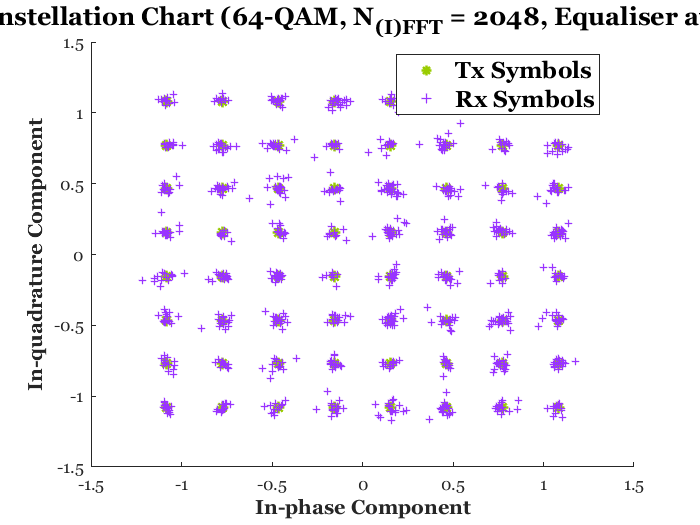

scatter(real(augmentedModulatedData(2:1024)), imag(augmentedModulatedData(2:1024)), [50], [0.6 0.8 0], 'Marker', '*', 'LineWidth', 1.5);
title('\bf\fontname{Georgia}\fontsize{15}Constellation Chart (64-QAM, N_{(I)FFT} = 2048, Equaliser at Rx)');
ylabel('\bf\fontname{Georgia}\fontsize{12}In-quadrature Component');
xlabel('\bf\fontname{Georgia}\fontsize{12}In-phase Component');
set(gca,'Fontname', 'Georgia');

hold on

scatter(real(Y(2:1024)), imag(Y(2:1024)), [20], [0.6 0.2 1], 'Marker', '+', 'LineWidth', 0.8);

legend({'\bf\fontname{Georgia}\fontsize{14}Tx Symbols', '\bf\fontname{Georgia}\fontsize{14}Rx Symbols'}, 'Location', 'best', 'Orientation', 'vertical');

hold off

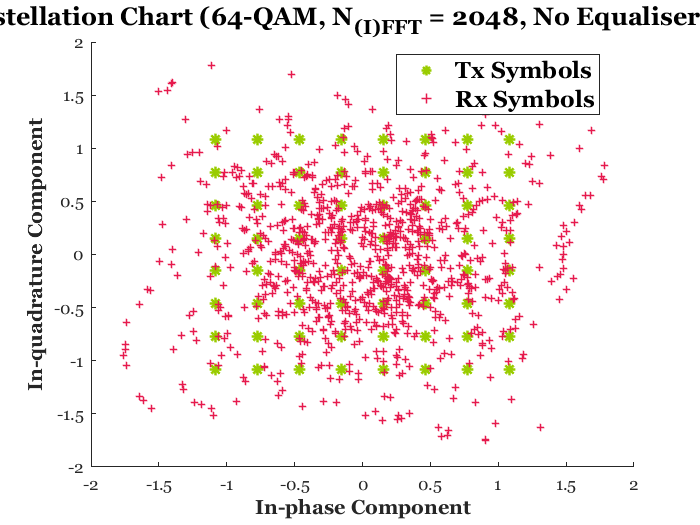


scatter(real(augmentedModulatedData(2:1024)), imag(augmentedModulatedData(2:1024)), [50], [0.6 0.8 0], 'Marker', '*', 'LineWidth', 1.5);
title('\bf\fontname{Georgia}\fontsize{15}Constellation Chart (64-QAM, N_{(I)FFT} = 2048, No Equaliser at Rx)');
ylabel('\bf\fontname{Georgia}\fontsize{12}In-quadrature Component');
xlabel('\bf\fontname{Georgia}\fontsize{12}In-phase Component');
set(gca,'Fontname', 'Georgia');

hold on

scatter(real(fftOp(2:1024)), imag(fftOp(2:1024)), [20], [0.9 0.1 0.3], 'Marker', '+', 'LineWidth', 0.85);

legend({'\bf\fontname{Georgia}\fontsize{14}Tx Symbols', '\bf\fontname{Georgia}\fontsize{14}Rx Symbols'}, 'Location', 'best', 'Orientation', 'vertical');

hold off

## Demodulation

demodOp = qamdemod(fftOp(2:1024) , M, "OutputType", "bit", "UnitAveragePower", true);

## Testing:

result = a-augmentedModulatedData.*fftChannel;

## Tx Vs Rx Symbols

% m = 1:length(modulatedData)
% 
% plot(m, abs(modulatedData), 'color', [0.4 1 0.1], 'Marker', '*', 'MarkerFaceColor', [0.4 1 0.1], 'MarkerSize', 9, 'LineStyle', ':', 'LineWidth', 0.6)
% title("Magnitude of Tx Vs Rx Symbols, \ith\rm\bf = [1 0.00 0.000]")
% ylabel('\bf\fontname{Georgia}Magnitude of Complex Symbol');
% xlabel('\bf\fontname{Georgia}\itm\rm\bf Index');
% set(gca,'Fontname', 'Georgia');
% xlim([0 1050])
% ylim([0 2])
% 
% hold on
% 
% plot(m, abs(fftOp(2:1024)), 'color', [0.4 0.8 1], 'Marker', 'o', 'MarkerFaceColor', [0.4 0.8 1], 'MarkerSize', 2.5, 'LineStyle', ':', 'LineWidth', 0.6)
% legend({'\bf\fontname{Georgia}Magnitude of Tx Symbols','\bf\fontname{Georgia}Magnitude of Rx symbol'}, 'Location', 'best', 'Orientation', 'vertical');
% 
% 
% hold off

## Get Rx Bits

rxBits = vitdec(demodOp, txTrellis, traceBackLength, 'cont', 'hard');
[number, ratio] = biterr(rxBits(34+1:end), data(1:end-34));

Some functions down here:

function y = channel(h, x)
    y = zeros(length(x), 1);
    filterLength = length(h)
    padSeq = zeros(filterLength - 1, 1);
    x = [padSeq; x]; % Padding x, so that we can implement the FIR input-output relationship more easily...
    for index = 1:length(y)
        y(index, 1) = sum(x(index:index + filterLength - 1, 1).*(flip(h')));
    end
end